Set-up the averaging FIR filter cascade

Fs=100e3;
Fnull=60; % frequency nulls and its multiple
N1=5;
N2=7;

Calculating where the nulls are:

for l=1:N1/2
nulls=Fs/N1*l    
end

nulls = 20000

nulls = 40000

Plotting the frequency response

StartFreq=1e0;
StopFreq=Fs;
NumbPnts=1000;
FreqStep=(StopFreq-StartFreq)/(NumbPnts-1);

FIR Nb 1 N=5

MagResp1=zeros(NumbPnts,1);
PhasResp1=zeros(NumbPnts,1);
Freq=zeros(NumbPnts,1);
for i=1:NumbPnts
    Freq(i)=StartFreq+(i-1)*FreqStep;
    H1=1/N1*sin(pi*Freq(i)*N1/Fs)/sin(pi*Freq(i)/Fs);
    MagResp1(i)=20*log10(abs(H1)^2); %calculating absolute magnitude in db
    PhasResp1(i)=angle(H1)*360/(2*pi); %calculating phase in degree
end


FIR Nb 2 N=7


MagResp2=zeros(NumbPnts,1);
PhasResp2=zeros(NumbPnts,1);

for i=1:NumbPnts
    Freq(i)=StartFreq+(i-1)*FreqStep;
    H2=1/N2*sin(pi*Freq(i)*N2/Fs)/sin(pi*Freq(i)/Fs);
    MagResp2(i)=20*log10(abs(H2)^2); %calculating absolute magnitude in db
    PhasResp2(i)=angle(H2)*360/(2*pi); %calculating phase in degree
end


Plot magnitude vs frequency--> H1

subplot(2,1,1)
HMag1=semilogx(Freq/1,MagResp1,'color','k','linewidth',2);
%set(gca,'FrontSize',12);
xlabel('Frequency (Hz)')
ylabel('Magnitude Response 1 (db)')
xlim([0 Fs/2]);
ylim([-100 5]);
grid on

Plot phase response--> H1

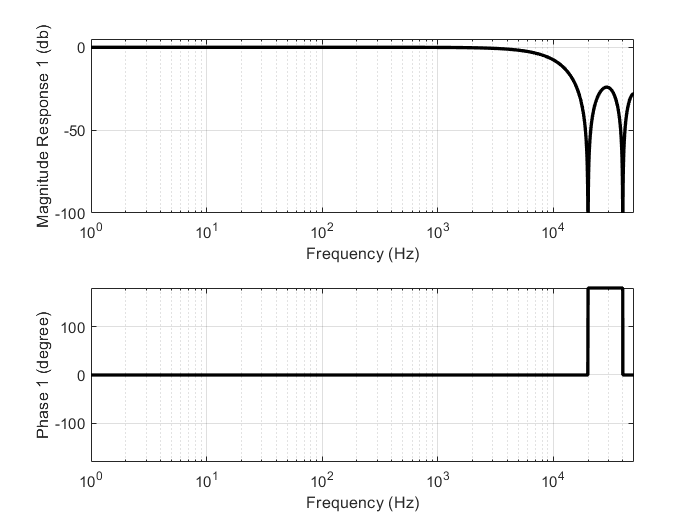

subplot(2,1,2)
Hphase1=semilogx(Freq/1,PhasResp1,'color','k','linewidth',2);
%set(gca,'FrontSize',12);
xlabel('Frequency (Hz)')
ylabel('Phase 1 (degree)')
xlim([0 Fs/2]);
ylim([-180 180]);
grid on

Plot magnitude vs frequency--> H2

subplot(2,1,1)
HMag2=semilogx(Freq/1,MagResp2,'color','k','linewidth',2);
%set(gca,'FrontSize',12);
xlabel('Frequency (Hz)')
ylabel('Magnitude Response 1 (db)')
xlim([0 Fs/2]);
ylim([-100 5]);
grid on

Plot phase response--> H2

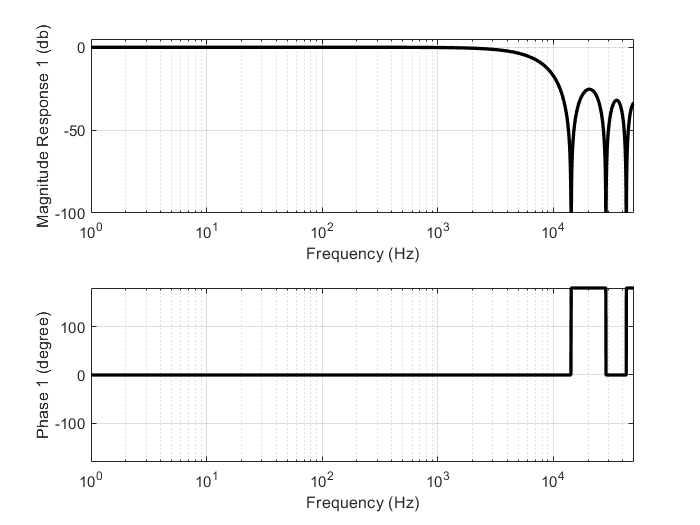

subplot(2,1,2)
Hphase2=semilogx(Freq/1,PhasResp2,'color','k','linewidth',2);
%set(gca,'FrontSize',12);
xlabel('Frequency (Hz)')
ylabel('Phase 1 (degree)')
xlim([0 Fs/2]);
ylim([-180 180]);
grid on

Plot magnitude vs frequency--> H2*H1

subplot(2,1,1)
HMagTot=semilogx(Freq/1000,MagResp1+MagResp2,'color','k','linewidth',2);
%set(gca,'FrontSize',12);
xlabel('Frequency (KHz)')
ylabel('Magnitude Response 1 (db)')
xlim([0 Fs/2000]);
ylim([-200 5]);
grid on

Plot phase response--> H2*H1

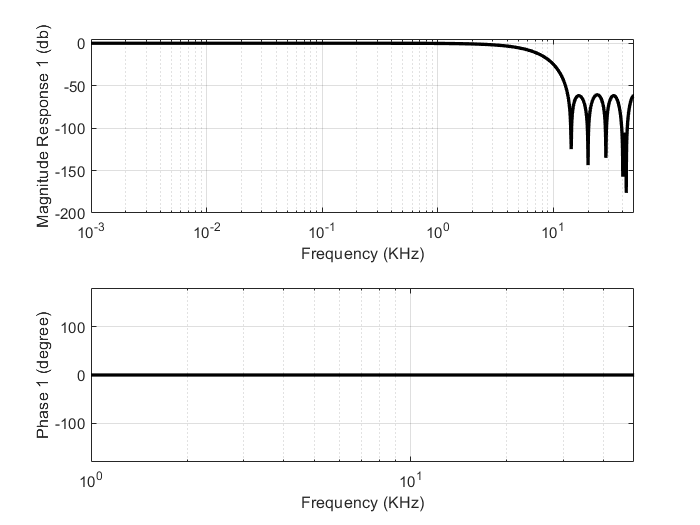

subplot(2,1,2)
HphaseTot=semilogx(Freq/1,PhasResp1+PhasResp2,'color','k','linewidth',2);
%set(gca,'FrontSize',12);
xlabel('Frequency (KHz)')
ylabel('Phase 1 (degree)')
xlim([0 Fs/2000]);
ylim([-180 180]);
grid on